# Create and Customize 3D Function Surface Plots

`fsurf` creates a surface plot of a function $z=f\left(x,y\right)$ over a default, or specified interval of $x$ and $y$.

### Create a Function

Define a function of two variables, $x$ and $y$, as an anonymous function which will be provided to `fsurf`.

fun1 = @(x,y) sin(x)+sin(y)-(x.^2+y.^2)/20;

### Basic Function Surface Plot

The provided function is plotted over the default x-y range from $\left\lbrack -5,5\right\rbrack$ in both directions.

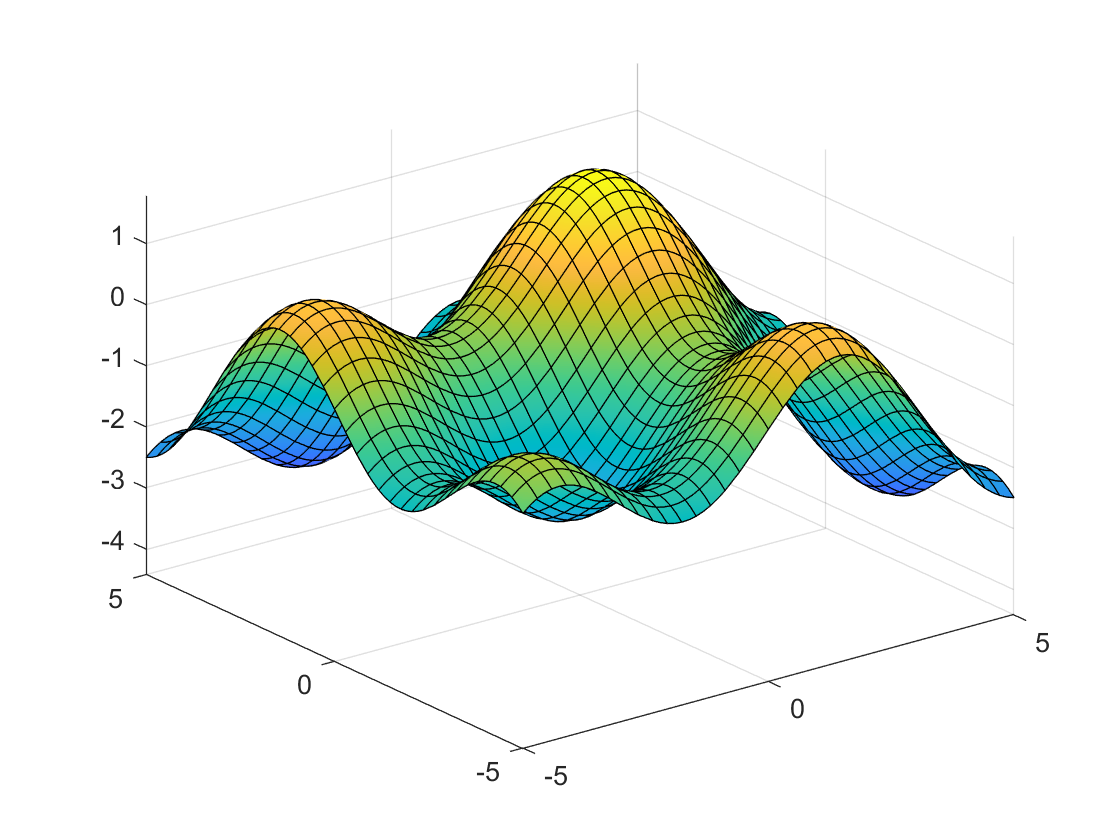

fsurf(fun1)

## Customizations

### Create a Smooth Surface

Remove the edge x-y axis lines from the surface by setting the *EdgeColor *property to "none". This creates a smooth surface with no edges.

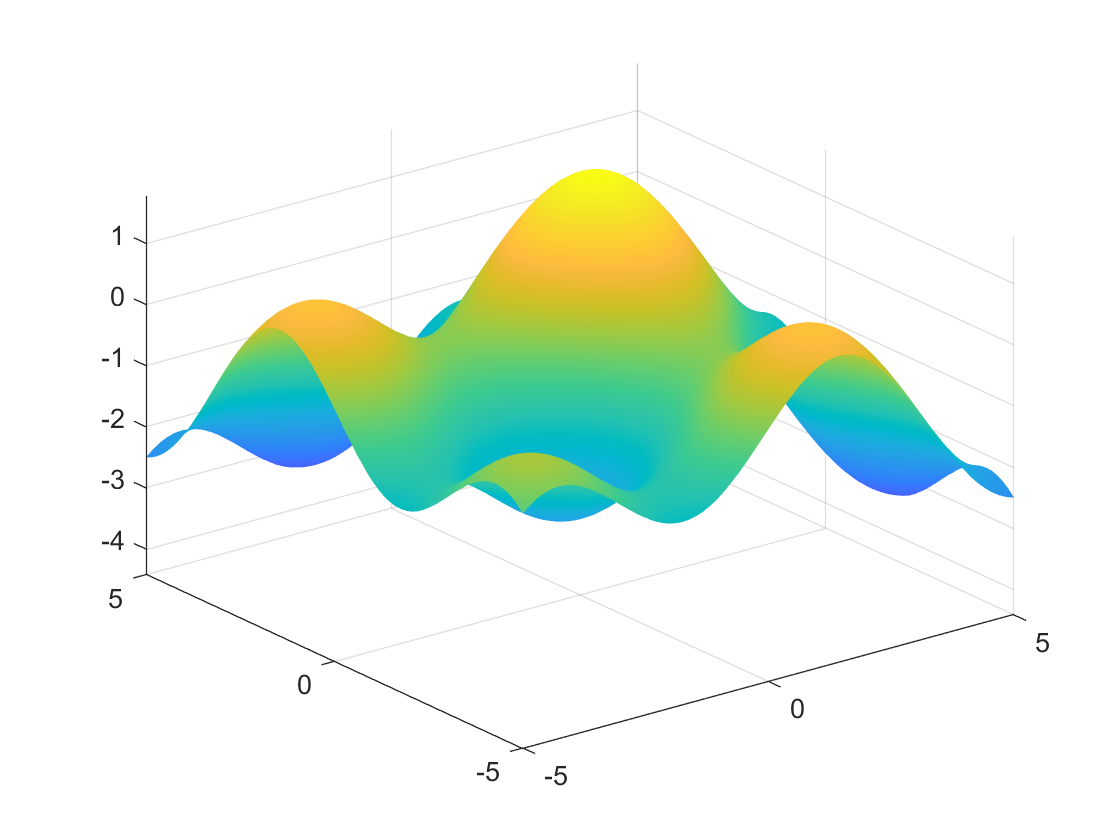

fsurf(fun1,...
    "EdgeColor","none")             % 

### Adjust the Surface Appearance

The overall image of the surface plot can be adjusted by specifying various lighting settings and surface color properties. The light source and light interaction with the plot is specified using the *camlight *and *lighting *properties. Various colormaps can be used for the surface which vary in color depending on the magnitude of the $z$-value. Additionally, the surface features can be extended onto a flat x-y plane at the bottom of the figure by enabling the *ShowContours *property. Increasing the *LineWidth *property will help improve the visualize of these contour lines.

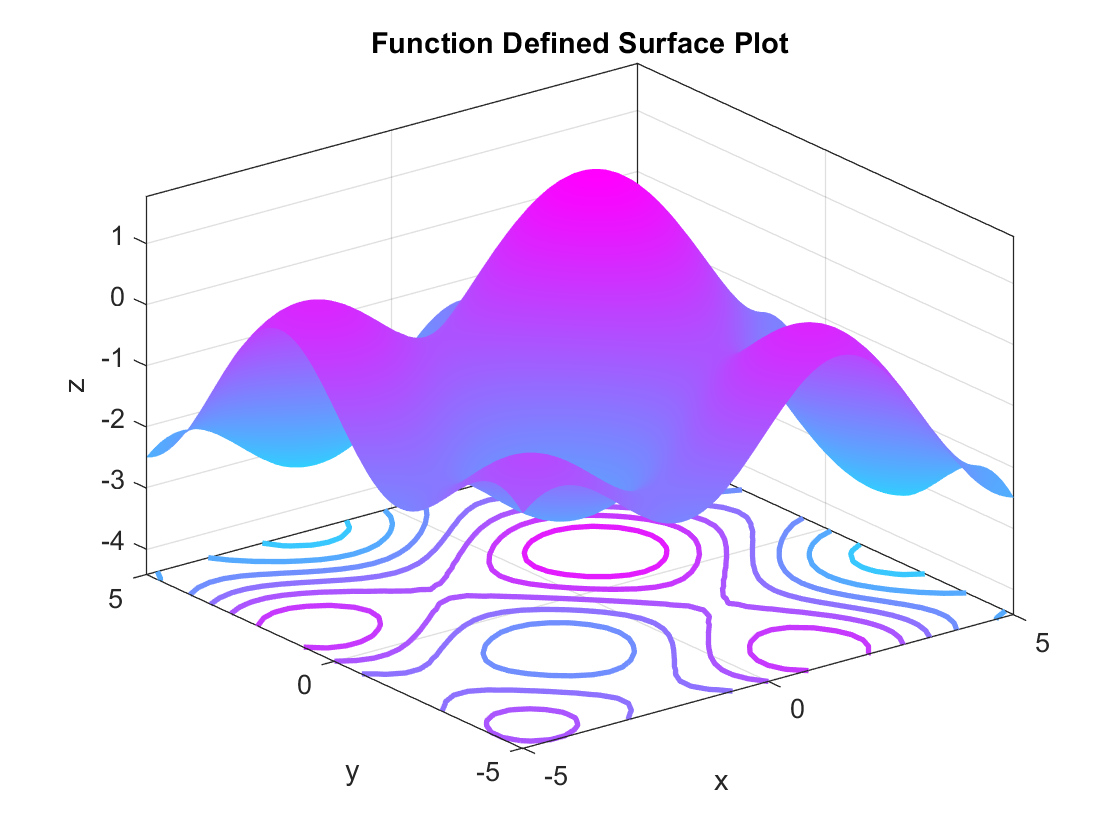

fs = fsurf(fun1,...
    "ShowContours","on",...
    "EdgeColor","none",...
    "LineWidth",2);
colormap("cool");                     % Specify colormap
lighting gouraud;                                   % best lighting algoithm for curved surfaces
material shiny
box on
axis tight                                          % Sets the axis limits equal to the range of the data

title('Function Defined Surface Plot')
xlabel('x')
ylabel('y')
zlabel('z')

## Additional Information

### Get all Fsurf Properties

Graphics objects in MATLAB have many properties. To see all the properties of a surface, uncomment the following code

% get(fs)

### Additional Information

Follow the link below to go to the documentation page to learn about the plot type in detail.

[fsurf](https://www.mathworks.com/help/matlab/ref/fsurf.html)